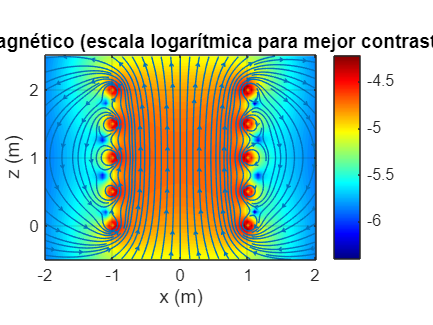

clc;
clear;
close all;

% Parámetros
R = 1;                  % Radio de las espiras (m)
N_theta = 100;          % Número de puntos por espira
N_loops = 5;            % Número de espiras
I = 10;                 % Corriente (A)
spacing = 0.5;          % Separación entre espiras (m)
mu0 = 4*pi*1e-7;        % Permeabilidad magnética del vacío

% Coordenadas angulares para parametrizar las espiras
theta = linspace(0, 2*pi, N_theta);

% Generación de espiras
z_pos = spacing * (0:N_loops-1);  % Posiciones z de cada espira
theta_grid = repmat(theta, 1, N_loops);
z_grid = repelem(z_pos, N_theta);

% Coordenadas cartesianas de todos los elementos de corriente
x_total = R * cos(theta_grid);
y_total = R * sin(theta_grid);
z_total = z_grid;

% Diferencias finitas para los elementos dl
dx_total = gradient(x_total);
dy_total = gradient(y_total);
dz_total = gradient(z_total);

% Malla de puntos donde calcular el campo
xmin = -2; xmax = 2; xstep = 0.05;
zmin = -0.5; zmax = (N_loops-1)*spacing + 0.5; zstep = 0.05;

[x_grid, z_grid] = meshgrid(xmin:xstep:xmax, zmin:zstep:zmax);
[nz, nx] = size(x_grid);
Bx = zeros(nz, nx);
Bz = zeros(nz, nx);

% Cálculo del campo magnético en todos los puntos usando la ley de Biot-Savart
for j = 1:length(x_total)
    r_source = [x_total(j); y_total(j); z_total(j)];
    dl = [dx_total(j); dy_total(j); dz_total(j)];

    % Vector r desde el elemento de corriente al punto de observación
    rx = x_grid - r_source(1);
    ry = - r_source(2);  % y=0 en los puntos de evaluación (simetría)
    rz = z_grid - r_source(3);

    r_norm = sqrt(rx.^2 + ry.^2 + rz.^2);
    valid = r_norm > 1e-6;  % Evitar división por cero cerca de la fuente

    % Producto cruz dl x r (solo componentes x y z necesarios)
    dBx = mu0*I/(4*pi) * (dl(2) * rz - dl(3) * ry) ./ (r_norm.^3);
    dBy = mu0*I/(4*pi) * (dl(3) * rx - dl(1) * rz) ./ (r_norm.^3); % no se usa
    dBz = mu0*I/(4*pi) * (dl(1) * ry - dl(2) * rx) ./ (r_norm.^3);

    % Sumar solo donde r_norm válido
    dBx(~valid) = 0;
    dBz(~valid) = 0;

    Bx = Bx + dBx;
    Bz = Bz + dBz;
end

% Magnitud del campo y transformación logarítmica para mejor visualización
Bmag = sqrt(Bx.^2 + Bz.^2);
Bmag_log = log10(Bmag + 1e-10);

% Visualización
figure;
contourf(xmin:xstep:xmax, zmin:zstep:zmax, Bmag_log, 100, 'LineColor', 'none');
colormap(jet);
colorbar;
hold on;
streamslice(xmin:xstep:xmax, zmin:zstep:zmax, Bx, Bz, 2);
title('Campo magnético (escala logarítmica para mejor contraste)');
xlabel('x (m)');
ylabel('z (m)');
axis equal;
grid on;


clim([1, -7]);  % Ajuste de escala de color

Error using clim (line 30)
Limits must be a 2-element vector of increasing numeric values.